clear all
rng(2)


% -----------------curve fitting--------------------------
% fr=8
n = 3

n = 3

knotintervals = 11;
xmax=1

xmax = 1

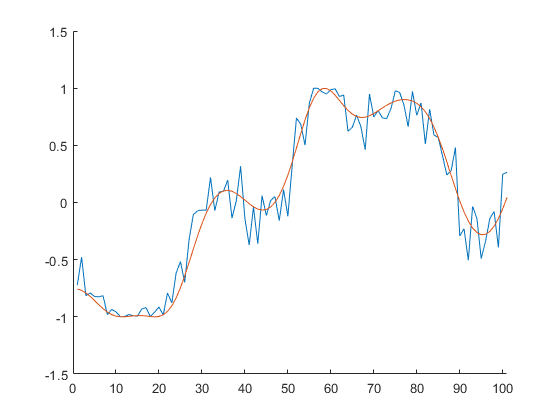


knotdist = xmax/knotintervals;
input = (0:0.01:xmax)';
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.8*(rand(size(input))-0.5));
real = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0*rand(size(input)));

bs = bspline([0:n+1]);
M = flipud(bs.coefs)';
figure;
hold on
axis([0 length(input) -1.5 1.5])
plot(output)
plot(real)
hold off

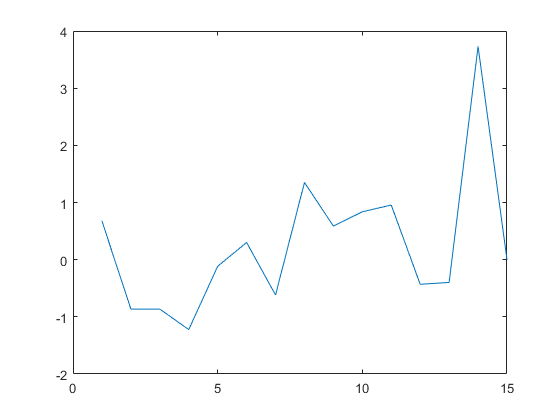


indexes = floor(input/knotdist)+1;

u = (input/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

B = zeros(length(input),knotintervals+n);
for i=1:length(input)
   B(i,indexes(i):indexes(i)+n) = bn(i,:);
end

P=pinv(B)*output;

spline = B*P;
plot(P)

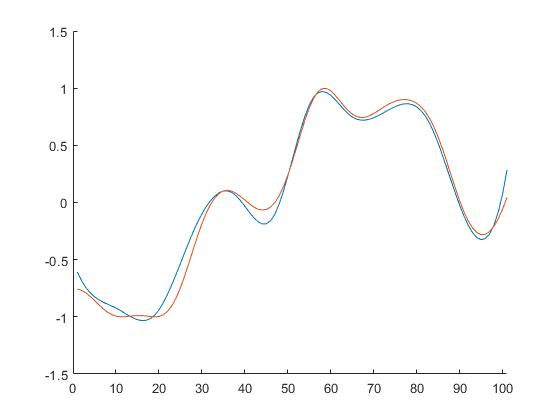


figure;
hold on
axis([0 length(output) -1.5 1.5])
% plot(output)
plot(spline)
plot(real)
hold off


err = immse(spline,real)

err = 0.0058

bb= input.^[34:-1:0]

bb =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0100    1.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   

P2=pinv(bb)*output

P2 = 	1.0e+10 *

   -1.0837
    4.8288
   -6.2810
   -0.7143
    4.8518
    2.2837
   -3.0182
   -3.9615
   -0.0697
    3.6119


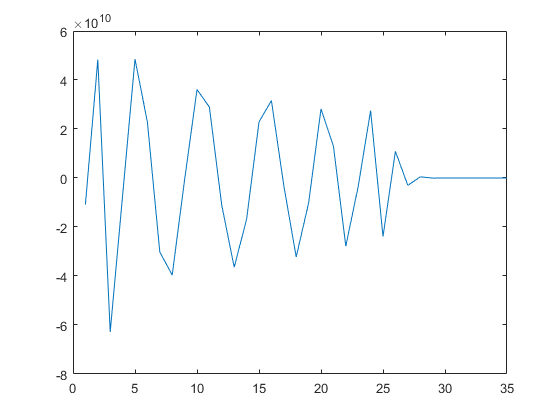

plot(P2)

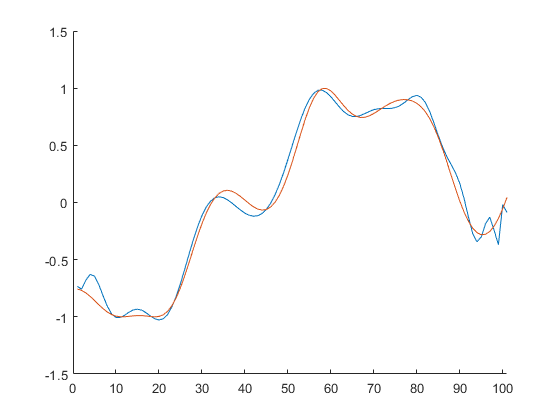


spline = bb*P2;

% spline = []
% for j = 1:(length(P)-n)
%    spline = [spline(1:end) ;bn*P(j:j+n)]; 
% end

figure;
hold on
axis([0 length(output) -1.5 1.5])
% plot(output)
plot(spline)
plot(real)
hold off

err = immse(spline,real)

err = 0.0062


% -----------------interpolation--------------------------
% fr=8
n = 3

n = 3


xmax=1

xmax = 1

dx=0.1

dx = 0.1000

input = (0:dx:xmax)';
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0*(rand(size(input))-0.5));
real = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0*rand(size(input)));

knotintervals = length(input)-1;
knotdist = dx%xmax/knotintervals;

knotdist = 0.1000

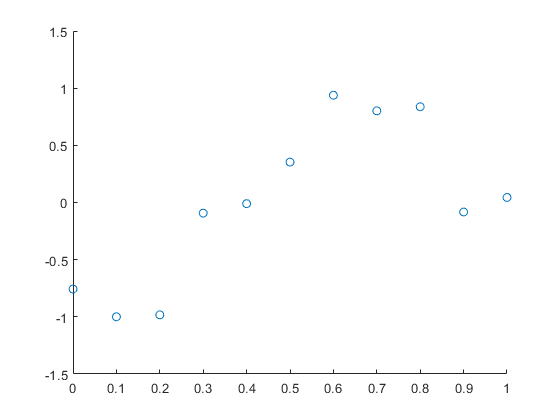


bs = bspline([0:n+1]);
M = flipud(bs.coefs)';
figure;
hold on
axis([0 xmax -1.5 1.5])
% scatter(1:11,output)
scatter(input,real)
hold off

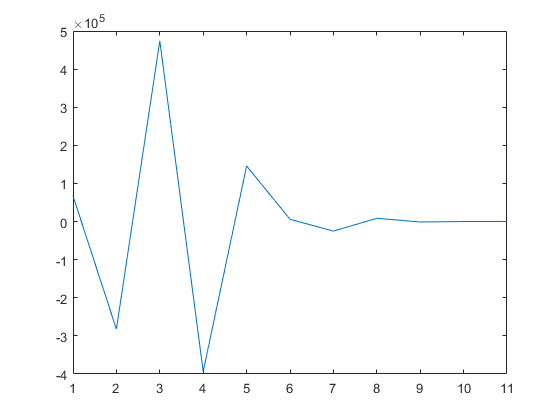


indexes = floor(input/knotdist)+1;

u = (input/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

B = zeros(length(input),knotintervals+n);
for i=1:length(input)
   B(i,indexes(i):indexes(i)+n) = bn(i,:);
end

P=pinv(B)*output;
% -------
bb= input.^[knotintervals:-1:0];
P2=pinv(bb)*output;
plot(P2);

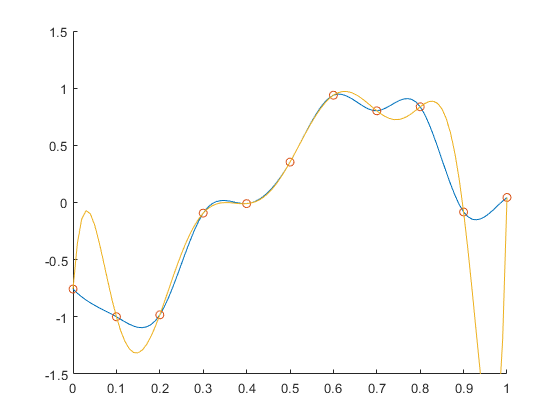


% -----
input2 = (0:dx/10:xmax)';
indexes = floor(input2/knotdist)+1;
u = (input2/knotdist)-indexes+1;
bn = u.^[n:-1:0]*M;

B = zeros(length(u),knotintervals+n);
for i=1:length(u)
   B(i,indexes(i):indexes(i)+n) = bn(i,:);
end

spline = B*P;
% plot(P);


figure;
hold on
axis([0 xmax -1.5 1.5])
% plot(output)
plot(input2,spline)
scatter(input,real)

bb= input2.^[knotintervals:-1:0];
spline = bb*P2;

plot(input2,spline)

hold off


% err = immse(spline,real)


